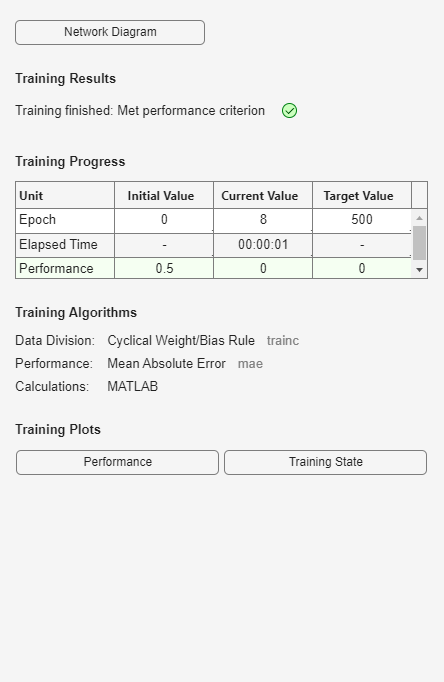

%福冈归属的感知器判别（变量除以平均值）
clear                                       %清理内存
P=[0.9282 0.9637 1.0169 1.1115 1.0583 0.9637 
0.7006 0.9100 1.0270 1.3535 1.2264 0.7049 
1.2065 1.1388 0.9427 0.9334 1.0094 0.6767 
2.0718 1.7399 0.9555 0.4928 0.4526 0.4626 
0.3634 0.5355 0.8798 1.5301 1.4344 1.0710]; %训练样本的输入变量
T=[1 1 0 0 0 1];                            %目标输出
Q=[0.9578 1.0776 1.0924 0.8247 1.1858]';    %待判样品（福冈）
net=newp(minmax(P),1);                      %创建一个感知器网络
net.trainParam.epochs=500;                  %指定最大训练次数
net=train(net,P,T);                         %网络训练

Yp=sim(net,P)                               %训练样品的预报结果

Yp =      1     1     0     0     0     1


Y=sim(net,Q)                                %待判样品的归类结果

Y = 0